% --- Variables necesarias definidas previamente ---
IPF = imread('20170829_174225.jpg'); 
% imshow(IPF)
Imagen_FILT = im2double(IPF);    
I_gray = rgb2gray(Imagen_FILT);    
I_gray_uint8 = im2uint8(I_gray);     

% Máscara del portaobjetos (campo de visión)
Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
fov_mask = segmentCellsStainBased(Imagen_mascara_gray);

% Canal 3 (núcleo) de imagen deconvolucionada
OD = -log(Imagen_FILT + 0.01);
OD = reshape(OD, [], 3);
W_manual = [
    0.650, 0.072, 0.707; 
    0.704, 0.990, 0.707; 
    0.286, 0.117, 0.000
];
W = W_manual ./ vecnorm(W_manual, 2, 2);
W = W';
C = OD * inv(W);
deconvolved_manual = reshape(C, size(IPF));
Imagen_nucleos = deconvolved_manual(:,:,3);

% Aplicación de fov_mask y binarización de núcleos
bw = imbinarize(Imagen_nucleos);
Imagen_masked = bw .* fov_mask;

% Datos de parásitos reales
fileID = fopen('20170829_174225.txt', 'r');
lines = textscan(fileID, '%s', 'Delimiter', '\n'); fclose(fileID); lines = lines{1};
lines(1) = [];
data = cell(length(lines), 7);
for i = 1:length(lines)
    tokens = strsplit(lines{i}, ',');
    for j = 1:7
        if j <= length(tokens)
            data{i, j} = tokens{j};
        else
            data{i, j} = '';
        end
    end
end
dataTable = cell2table(data, 'VariableNames', {'ID','Label','Comment','Shape','NumPoints','X1','Y1'});
dataTable.X1 = str2double(dataTable.X1); dataTable.Y1 = str2double(dataTable.Y1);
solo_parasitos = dataTable(ismember(dataTable.Label, {'Parasite', 'Parasitized'}), :);

## **SEGMENTACIÓN BASADA EN K-MEANS**

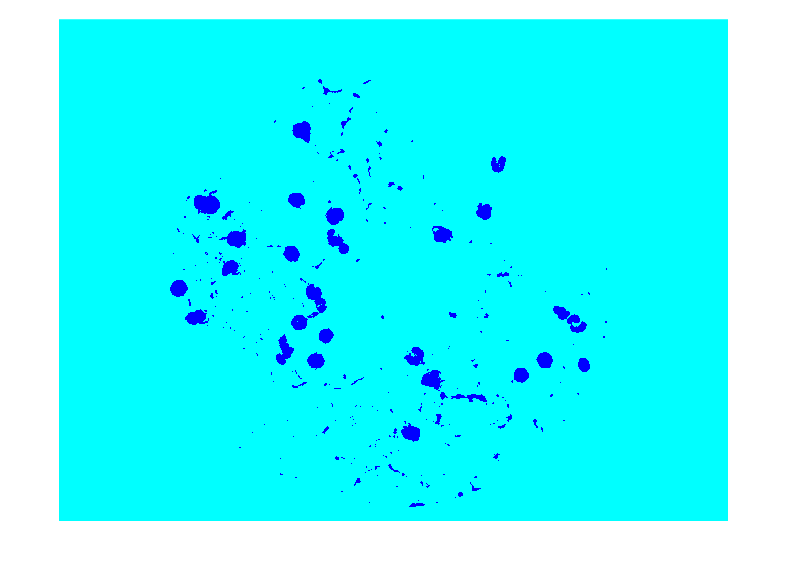

rng(1);
cform = makecform('srgb2lab');
lab_Image = applycform(Imagen_FILT, cform);
ab = double(lab_Image(:,:,2:3));
nrows = size(ab,1);
ncols = size(ab,2);
ab = reshape(ab, nrows*ncols, 2);

nColors = 2;  
[cluster_idx, cluster_center] = kmeans(ab, nColors, 'distance', 'sqEuclidean', 'Replicates', 3);

pixel_labels = reshape(cluster_idx, nrows, ncols);
rgb_label = label2rgb(pixel_labels);

figure; imshow(rgb_label);

% title('Segmentación con K-means (color por clúster)');

% Mostrar clúster de interés (asumiendo el clúster 1)
mask = pixel_labels == 1;

cluster1_img = Imagen_FILT;
cluster1_img(repmat(~mask, [1, 1, 3])) = 0;

% figure;
% imshow(cluster1_img);
% title('Clúster 1: de interés');

% Convertir la máscara en binaria
mask_bin = mask;

% Obtener los objetos conectados
cc = bwconncomp(mask_bin);
stats = regionprops(cc, 'Area');

% Definir el umbral de área mínima
area_minima = 1500;

% Crear máscara vacía
mask_largest = false(size(mask_bin));

% Conservar solo los objetos que superen el área mínima
for i = 1:length(stats)
    if stats(i).Area > area_minima
        mask_largest(cc.PixelIdxList{i}) = true;
    end
end

% Dilatar la máscara de los objetos seleccionados
se = strel('disk', 10);  
mask_dilated = imdilate(mask_largest, se);

% imshow(mask_dilated);
% title('Máscara dilatada de glóbulos blancos');

% Paso 4: Obtener solo objetos pequeños 
mask_obj_peq = mask & ~mask_dilated;

% Aplicar esta nueva máscara a la imagen original del clúster
solo_obj_peq = Imagen_FILT;
solo_obj_peq(repmat(~mask_obj_peq, [1, 1, 3])) = 0;

% --- Paso 6: Convertir a gris si es RGB ---
if ndims(solo_obj_peq) == 3 && size(solo_obj_peq,3) == 3
    imagenSegmentableGray = rgb2gray(solo_obj_peq);
else
    imagenSegmentableGray = solo_obj_peq;
end

% --- Paso 7: Segmentación K-means para parásitos ---
datosParasitos = double(imagenSegmentableGray(:));
numClustersParasitos = 3;

[idxParasitos, CParasitos] = kmeans(datosParasitos, numClustersParasitos, 'Replicates', 3);

% Cluster más oscuro (asumido parásitos)
[~, idxParasitico] = min(CParasitos);

mascaraParasitoseRuido = reshape(idxParasitos == idxParasitico, size(imagenSegmentableGray));

% --- Paso 8: Filtrar objetos pequeños ---
areaMinimaParasitos = 700;
mascaraParasitoseRuidoFiltrada = bwareafilt(mascaraParasitoseRuido, [areaMinimaParasitos Inf]);

% Usar imfindcircles sobre la imagen de bordes
[centros_parasitos, radios_parasitos] = imfindcircles(~mascaraParasitoseRuidoFiltrada, [2 10], 'Sensitivity', 0.92, 'EdgeThreshold', 0.1);

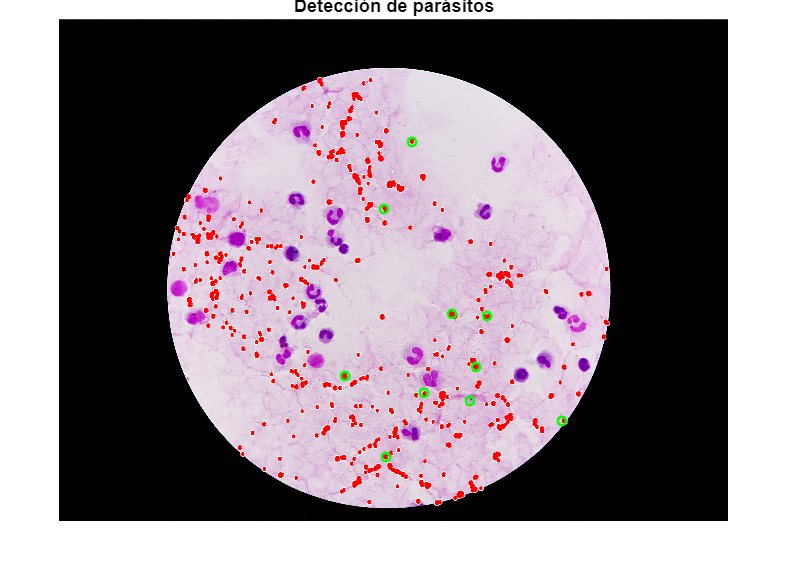


% Contar parásitos detectados automáticamente y reales
num_auto = size(centros_parasitos, 1);
num_reales = size(solo_parasitos, 1);
num_total = num_auto + num_reales;

% Mostrar resultados sobre la imagen original (color)
figure; imshow(IPF);
title('Detección de parásitos');
hold on;

% Dibujar círculos detectados (automáticos)
viscircles(centros_parasitos, radios_parasitos, 'EdgeColor', 'r');

% Dibujar parásitos reales (desde archivo)
plot(solo_parasitos{:,6}, solo_parasitos{:,7}, 'go', 'MarkerSize', 5, 'LineWidth', 1.5);

hold off;


% --- Paso 14: Contar detecciones automáticas y reales ---
numDetectadosAuto = size(centros_parasitos, 1);
numParasitosReales = size(solo_parasitos, 1);
numTotalParasitos = numDetectadosAuto + numParasitosReales;

fprintf('Parásitos detectados automáticamente: %d\nParásitos reales anotados: %d\nTotal parásitos: %d\n', ...
    numDetectadosAuto, numParasitosReales, numTotalParasitos);

Parásitos detectados automáticamente: 512
Parásitos reales anotados: 10
Total parásitos: 522



% --- Paso 15: Validar detecciones automáticas contra parásitos reales ---
radioExtra = 20;
aciertosDeteccion = 0;

for i = 1:numParasitosReales
    puntoReal = [solo_parasitos{i,6}, solo_parasitos{i,7}];
    for j = 1:numDetectadosAuto
        centroDet = centros_parasitos(j,:);
        radioDet = radios_parasitos(j) + radioExtra;
        distancia = norm(puntoReal - centroDet);
        if distancia <= radioDet
            aciertosDeteccion = aciertosDeteccion + 1;
            break;
        end
    end
end

falsosPositivos = numDetectadosAuto - aciertosDeteccion;
falsosNegativos = numParasitosReales - aciertosDeteccion;

fprintf('Parásitos correctamente detectados: %d de %d reales\n', aciertosDeteccion, numParasitosReales);

Parásitos correctamente detectados: 9 de 10 reales


fprintf('Falsos positivos: %d\n', falsosPositivos);

Falsos positivos: 503


fprintf('Falsos negativos: %d\n', falsosNegativos);

Falsos negativos: 1


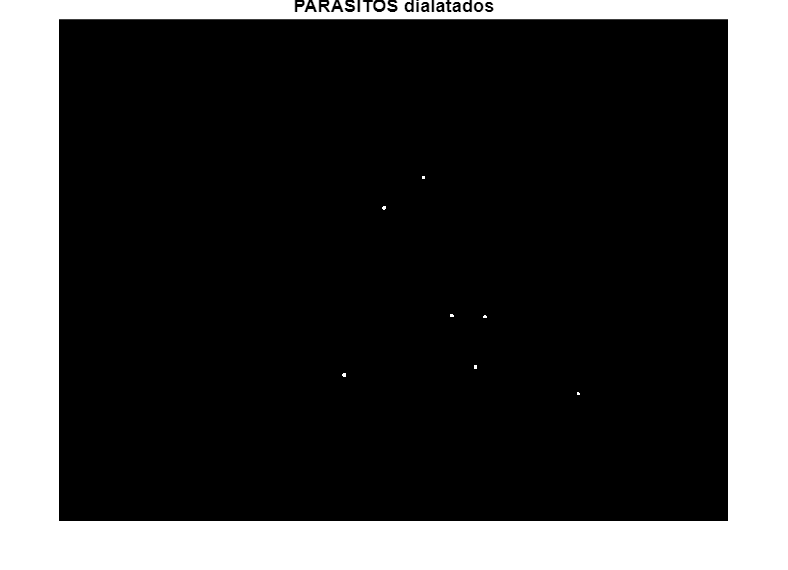


% --- Paso 16: Asociar objetos segmentados a parásitos reales ---
x_real = solo_parasitos{:,6};
y_real = solo_parasitos{:,7};
propsObjetos = regionprops(mascaraParasitoseRuido, 'Centroid', 'Area', 'Perimeter', 'PixelIdxList');
indicesObjetosAsignados = zeros(length(x_real), 1);

for i = 1:length(x_real)
    centroides = reshape([propsObjetos.Centroid], 2, [])';
    distancias = sqrt((centroides(:,1) - x_real(i)).^2 + (centroides(:,2) - y_real(i)).^2);
    [~, idxMin] = min(distancias);
    indicesObjetosAsignados(i) = idxMin;
end

% --- Paso 17: Extraer canales RGB e intensidades medias de parásitos reales ---
R = IPF(:,:,1); G = IPF(:,:,2); B = IPF(:,:,3);
intensidadR = zeros(length(x_real),1);
intensidadG = zeros(length(x_real),1);
intensidadB = zeros(length(x_real),1);

mascaraParasitosFinal = false(size(mascaraParasitoseRuido));

areasParasitos = zeros(length(x_real), 1);
circularidadParasitos = zeros(length(x_real), 1);

for i = 1:length(indicesObjetosAsignados)
    idx = indicesObjetosAsignados(i);
    objeto = propsObjetos(idx);
    areasParasitos(i) = objeto.Area;
    if objeto.Perimeter > 0
        circularidadParasitos(i) = 4 * pi * objeto.Area / (objeto.Perimeter^2);
    else
        circularidadParasitos(i) = NaN;
    end

    mascaraParasitosFinal(objeto.PixelIdxList) = true;
    intensidadR(i) = mean(R(objeto.PixelIdxList));
    intensidadG(i) = mean(G(objeto.PixelIdxList));
    intensidadB(i) = mean(B(objeto.PixelIdxList));
end

% Paso 18: Visualizar parásitos reales sobre imagen original (color)
imagenParasitosColor = zeros(size(IPF), 'like', IPF);
for canal = 1:3
    tempCanal = IPF(:,:,canal);
    tempCanal(~mascaraParasitosFinal) = 0;
    imagenParasitosColor(:,:,canal) = tempCanal;
end

% figure;
% imshow(imagenParasitosColor);
% title('Parásitos reales (color original)');

% --- Paso 19: Dilatar máscara binaria de parásitos reales ---
parasitosGris = rgb2gray(imagenParasitosColor);
mascaraBinariaParasitos = parasitosGris > 0;

elementoEstructuranteDil = strel('disk', 10);
mascaraParasitosDil = imdilate(mascaraBinariaParasitos, elementoEstructuranteDil);

figure;
imshow(mascaraParasitosDil);
title('PARÁSITOS dialatados');

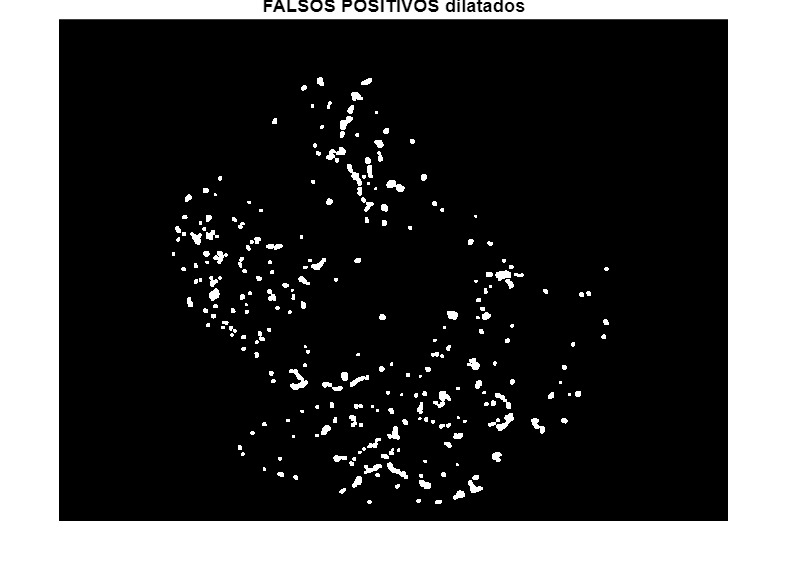


% --- Paso 20: Detectar falsos positivos ---
% Invertir la máscara binaria de parásitos dilatada
mascara_parasitos_invertida = ~mascaraParasitosDil;

% Aplicar la máscara invertida a la imagen segmentada original (con posibles falsos positivos)
bw_falsos_positivos = mascaraParasitoseRuidoFiltrada & mascara_parasitos_invertida;

% Dilatar para visualización (opcional)
bw_falsos_positivos = imdilate(~bw_falsos_positivos, se);

% Mostrar el resultado
figure;
imshow(bw_falsos_positivos);
title('FALSOS POSITIVOS dilatados');

function fov_mask  = segmentCellsStainBased(I)

    if size(I, 3) == 3
        I = rgb2gray(I);
    end
   
    level = graythresh(I);
    bw = imbinarize(I, level);
   
    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end
   
    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');

    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');
   
    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;
   
    adjusted_radius = max(circle_radius - 15, 0);
   
    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);

    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;

end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

% Función REGION GROWING
function region_mask = regionGrowing(img, seed_point, intensity_thresh, max_size)
    region_mask = false(size(img));
    to_visit = seed_point;
    region_intensity_mean = double(img(seed_point(2), seed_point(1)));
    count = 0;
    while ~isempty(to_visit) && count < max_size
        current = to_visit(1,:);
        to_visit(1,:) = [];
        x = current(1);
        y = current(2);
        
        if x<1 || y<1 || x>size(img,2) || y>size(img,1)
            continue;
        end
        
        if region_mask(y,x)
            continue; % ya visitado
        end
        
        intensity = double(img(y,x));
        if abs(intensity - region_intensity_mean) <= intensity_thresh
            region_mask(y,x) = true;
            count = count + 1;
            % Añadir vecinos 8-conectados
            vecinos = [x-1,y-1; x,y-1; x+1,y-1; x-1,y; x+1,y; x-1,y+1; x,y+1; x+1,y+1];
            to_visit = [to_visit; vecinos]; % añadir al final
            % Actualizar intensidad media
            region_intensity_mean = (region_intensity_mean*(count-1) + intensity) / count;
        end
    end
end
